This is just a throwaway script, but it could be handy.

Let's look at historical temperature, to see when the RCP scenarios diverge. 

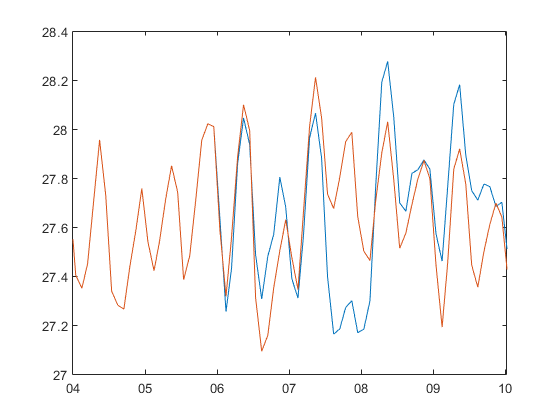

load('./ESM2M_SSTR_JD.mat');

% Global means
t26 = mean(SSTR_2M26_JD,1);
t45 = mean(SSTR_2M45_JD,1);
t60 = mean(SSTR_2M60_JD,1);
t85 = mean(SSTR_2M85_JD,1);
plot(Time, t26); hold on;
plot(Time, t45);
% Make ticks land on years of interest
startDate = datenum('01-01-2004');
endDate = datenum('01-10-2010');
xlim([startDate endDate])

datetick('x', 'yy', 'keeplimits')

That didn't show much difference, but there is a difference of up to about 0.6 C starting in 2006..  Let's look at variance of the time series up to 2000, which has a datenum of 730486 and an index of about 1668 in the Time array.

v26 = var(SSTR_2M26_JD(1:1668))

v26 = 4.8867

v45 = var(SSTR_2M45_JD(1:1668))

v45 = 4.8867

v60 = var(SSTR_2M60_JD(1:1668))

v60 = 4.8867

v85 = var(SSTR_2M85_JD(1:1668))

v85 = 4.8867